#### DATA MINING AND NEURAL NETWORKS

#### Prof. Dr. ir. Johan A. K. Suykens

#### Assignment 1 - Part 3 (exercise)

# Bayesian Inference

# (exercise)

*Copyright of this version: HENRI DE PLAEN, KU LEUVEN*

*(based on previous works of the same course)*

*Date: 18 October 2019*

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%% DATA MINING AND NEURAL NETWORKS                                   %%%%
%%%% Prof. Dr. ir. Johan A. K. Suykens                                 %%%%
%%%% Assignment 1 - Part 3                                             %%%%
%%%% Bayesian Inference (exercise)                                     %%%%
%%%%                                                                   %%%%
%%%% Copyright of this version: HENRI DE PLAEN, KU LEUVEN              %%%%
%%%% (based on previous works of the same course)                      %%%%
%%%% Date: 18 October 2019                                             %%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

Clears all variables stored in the workspace and closes all extra windows (e.g. plots or neural network training windows).

clear all ; close all ; clc ;

## ALGORLM

A script comparing performance of `trainlm` and '`traingd`'

- `traingd` - batch gradient descent 

- `trainlm` - Levenberg - Marquardt

### Generation of examples and targets


x = 0:0.05:3*pi ;   % input
noise = 0.5*randn(1,length(x));
y = sin(x.^2) +noise ;     % output
y1 = sin(x.^2);
p = con2seq(x) ;    % converts the input to a best format for the toolbox
t = con2seq(y) ;    % converts the output to a best format for the toolbox
figure
hold on 
plot(x,y)
plot(x,y-noise)

### Creation of networks

Why is it relevant to put the same weights and biases for both networks?

net1 = feedforwardnet([50,20 10],'trainlm') ;   % creates a forst net with the 'trainlm' algorithm
net2 = feedforwardnet([50,20 10],'traincgf') ;  % creates a second network with the 'trainbfg' algorithm
net2.iw{1,1} = net1.iw{1,1} ;           % sets the same weights for both networks
net2.lw{2,1} = net1.lw{2,1} ;           % sets the same weights for both networks
net2.b{1} = net1.b{1} ;                 % sets the same biases for both networks
net2.b{2} = net1.b{2} ;                 % sets the same biases for both networks


### Training and simulation

Due to local minima, each training is different. If wou want general conclusions, you should work on a mean of many different examples. Why would it be relevant here, or not?

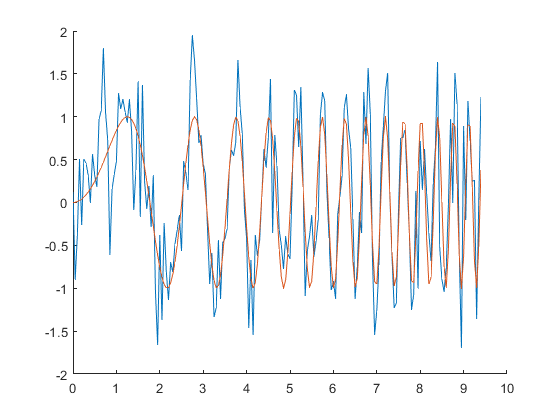

net1.trainParam.epochs = 1 ;            % set the number of epochs for the training (network 1)
net2.trainParam.epochs = 1 ;            % set the number of epochs for the training (network 2)
[net1,tr11] = train(net1,p,t) ;                % train network 1
[net2,tr12]  = train(net2,p,t) ;                % train network 2

a11 = sim(net1,p) ;                     % simulate network 1 with the input vector p
a21=sim(net2,p) ;                       % simulate network 2 with the input vector p

net1.trainParam.epochs = 14 ;
net2.trainParam.epochs = 14 ;
[net1,tr21] = train(net1,p,t) ;
[net2,tr22] = train(net2,p,t) ;
a12 = sim(net1,p) ; 
a22 = sim(net2,p) ;

net1.trainParam.epochs = 985 ;
net2.trainParam.epochs = 985 ;
[net1,tr31] = train(net1,p,t) ;
[net2,tr32] = train(net2,p,t) ;
a13 = sim(net1,p) ; 
a23 = sim(net2,p) ;


### Plots

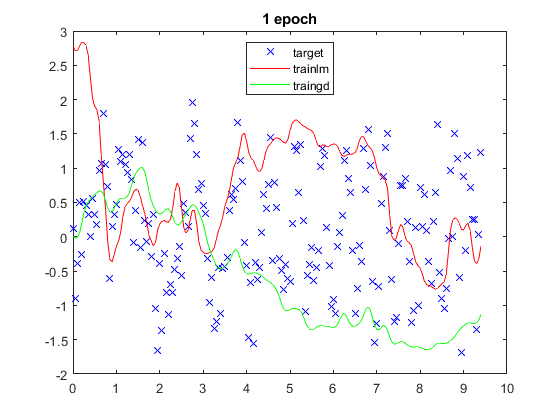



figure
plot(x,y,'bx',x,cell2mat(a11),'r',x,cell2mat(a21),'g'); % plot the sine function and the output of the networks
title('1 epoch');
legend('target','trainlm','traingd','Location','north');

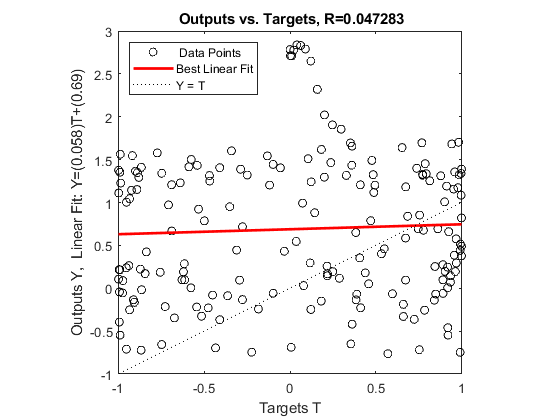

figure
[~,~,r11]=postreg(cell2mat(a11),y1); % perform a linear regression analysis and plot the result

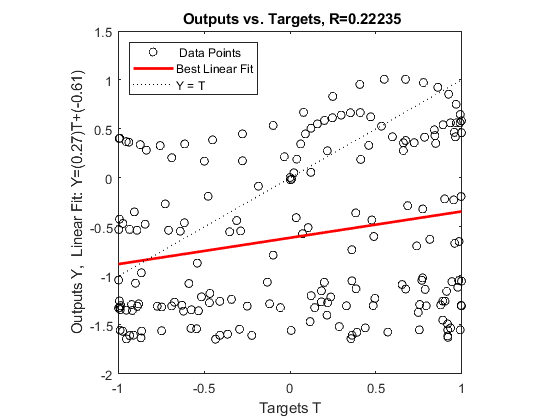

figure
[~,~,r21]=postreg(cell2mat(a21),y1);

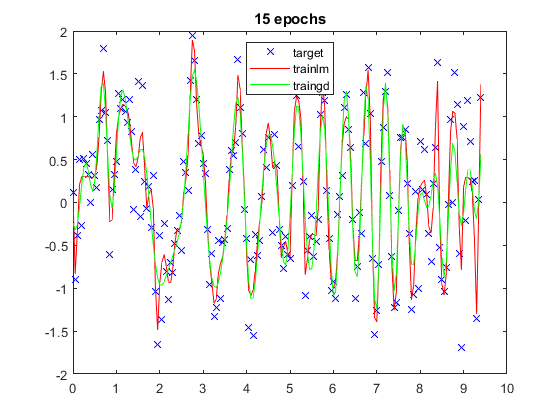


figure
plot(x,y,'bx',x,cell2mat(a12),'r',x,cell2mat(a22),'g');
title('15 epochs');
legend('target','trainlm','traingd','Location','north');

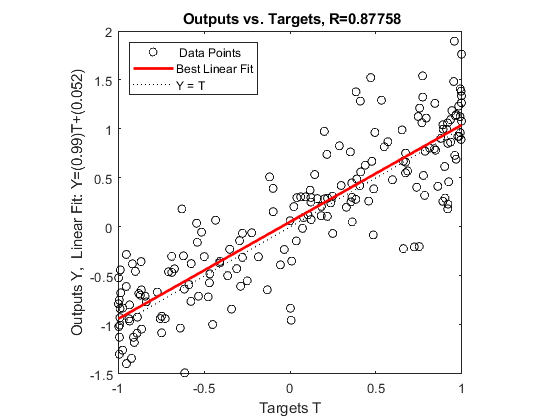

figure
[~,~,r12]=postreg(cell2mat(a12),y1);

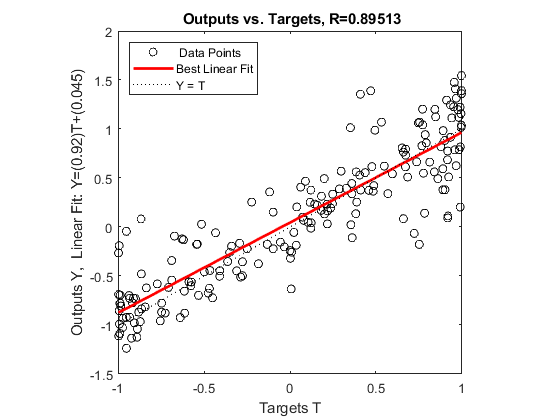

figure
[~,~,r22]=postreg(cell2mat(a22),y1);

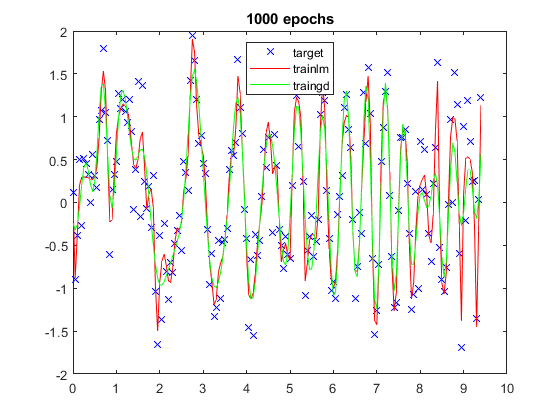


figure
plot(x,y,'bx',x,cell2mat(a13),'r',x,cell2mat(a23),'g');
title('1000 epochs');
legend('target','trainlm','traingd','Location','north');

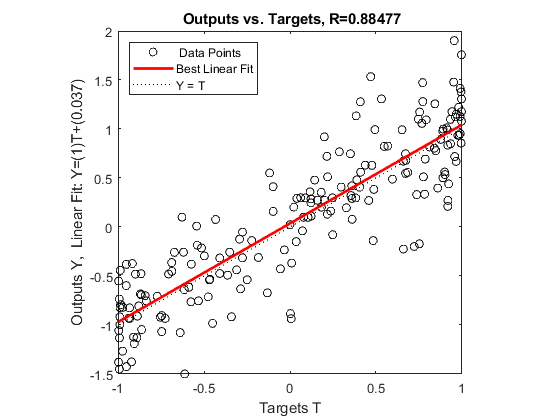

figure
[~,~,r13]= postreg(cell2mat(a13),y1);

figure
[~,~,r23]=postreg(cell2mat(a23),y1);


a=[
max(tr31.time);
max(tr32.time)]

a =     1.1580
    1.8790



r=[r11;r12;r13;r21;r22;r23]

r =     0.0473
    0.8776
    0.8848
    0.2224
    0.8951
    0.8951
